**Graficar puntos y lineas**

Se utiliza la función *plot()* para 2D y *plot3() *para 3D.

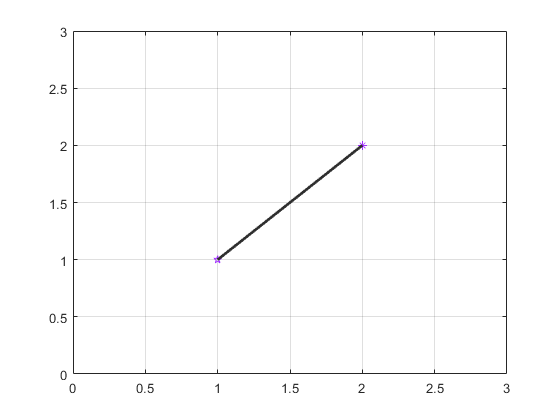

% Graficar un punto
punto = [2 2];
punto2 = [1 1];
figure
plot(punto(1),punto(2),'*','color',[.635 .188 1])
grid on
hold on
plot(punto2(1),punto2(2),'p','color',[.635 .188 1])
plot([punto(1) punto2(1)],[punto(2) punto2(2)],...
    'color',[.18 .18 .18],'LineWidth',2)
axis([0 3 0 3])

**Graficar vectores en Matlab**

Para graficar vectores en 2D se utiliza la funcion *quiver()*.

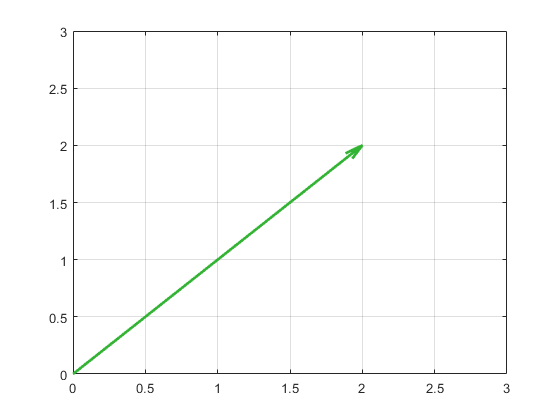

Po = [0 0];
Pf = [2 2];
figure
quiver(Po(1),Po(2),Pf(1),Pf(2),0,...
    'color',[0.2 0.7 0.2],'LineWidth',2)
grid on
axis([0 3 0 3])

Codigo de colores de un sistema de coordenadas

x -> rojo

y-> verde

z -> azul

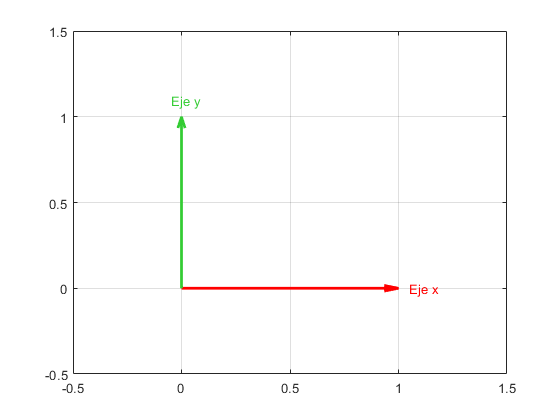

figure
% Eje x
quiver(0,0,1,0,0,'color',[1 0 0],...
    'LineWidth',2)
hold on
grid on
text(1.05,0,'Eje x','color',[1 0 0])
% Eje y
quiver(0,0,0,1,0,'color',[0.2 0.8 0.2],...
    'LineWidth',2)
text(-0.05,1.1,'Eje y','color',[0.2 0.8 0.2])
axis([-0.5 1.5 -0.5 1.5])

**Vectores en 3D**

Se utiliza la funcion **quiver3()**

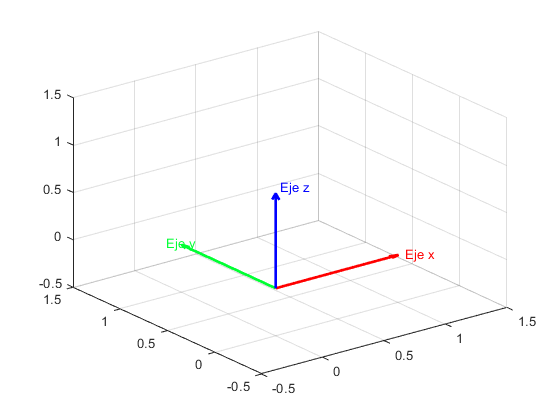

figure
% Eje x
quiver3(0,0,0,1,0,0,0,'color',[1 0 0],...
    'LineWidth',2)
hold on
grid on
text(1.05,0,0,'Eje x','color',[1 0 0])
% Eje y
quiver3(0,0,0,0,1,0,0,'color',[0 1 0.2],...
    'LineWidth',2)
text(-0.05,1.1,0,'Eje y','color',[0 1 0.2])
% Eje z
quiver3(0,0,0,0,0,1,0,'color',[0 0 1],...
    'LineWidth',2)
text(0,-0.05,1.1,'Eje z','color',[0 0 1])
axis([-0.5 1.5 -0.5 1.5 -0.5 1.5])

**Rotaciones usando el toolbox de peter corke**

Matriz de rotación es una matriz de proyecciones entre vectores unitarios, en general son de dimensión 3X3 y pertenecen al grupo especial SO(3). Se tienen 3 rotaciones básicas en el espacio: 


$$\mathrm{rotz}\left(\alpha \right)=\left\lbrack \begin{array}{ccc}
\mathrm{cos}\left(\alpha \right) & -\mathrm{sin}\left(\alpha \right) & 0\\
\mathrm{sin}\left(\alpha \right) & \mathrm{cos}\left(\alpha \right) & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


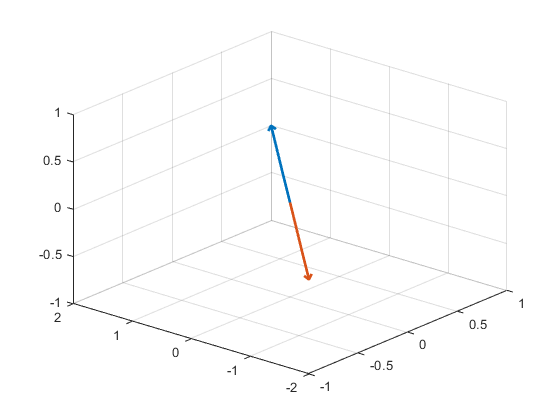

% Rotacion de un vector (Rotacion en Z)
Pinit = [1 2 0]';
matR = rotz(pi);
Prot = matR*Pinit;
figure
quiver3(0,0,0,Pinit(1),Pinit(2),Pinit(3),0,...
    'LineWidth',2)
hold on 
grid on
quiver3(0,0,0,Prot(1),Prot(2),Prot(3),0,...
    'LineWidth',2)
view(-50,30) % Permite cuadrar prespectiva de la grafica

Revisar la función del toolbox *trplot*

Cómo generar una matriz identidad 4x4?